func = @(x) x.^2 - 4.*x + 4 - log(x)

func = function_handle with value:
    @(x)x.^2-4.*x+4-log(x)



a1 = 1, b1 = 2

a1 = 1

b1 = 2

a2 = 2, b2 = 4

a2 = 2

b2 = 4

max_iter = 100

max_iter = 100


% tolerance
tol = 1e-5

tol = 1.0000e-05

[root1, iter1, tab1] = bisection_method_function(...
    a1, b1, tol, max_iter, func ...
)

root1 = 1.4124

iter1 = 17

tab1 = 17×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             1       -0.69315       -0.15547
      2          1       1.5      1.25             1       -0.15547        0.33936
      3       1.25       1.5     1.375       0.33936       -0.15547       0.072171
      4      1.375       1.5    1.4375      0.072171       -0.15547      -0.046499
      5      1.375    1.4375    1.4062      0.072171      -0.046499       0.011612
      6     1.4062    1.4375    1.4219      0.011612      -0.046499      -0.017748
      7     1.4062    1.4219    1.4141      0.011612      -0.017748      -0.003

[root2, iter2, tab2] = bisection_method_function( ...
    a2, b2, tol, max_iter, func ...
)

root2 = 3.0571

iter2 = 16

tab2 = 16×7 table
    iter      a         b         p           f_a           f_b            f_p    
    ____    ______    ______    ______    ___________    __________    ___________

      1          2         4         3       -0.69315        2.6137      -0.098612
      2          3         4       3.5      -0.098612        2.6137        0.99724
      3          3       3.5      3.25      -0.098612       0.99724        0.38385
      4          3      3.25     3.125      -0.098612       0.38385        0.12619
      5          3     3.125    3.0625      -0.098612       0.12619      0.0096747
      6          3    3.0625    3.0312      -0.098612     0.0096747      -0.045499
      7     3.0312    3.0625    3.0469      -0.045499     0.0096747      -0.018

fprintf( ...
    "root1 = %f; iteration = %d\n" + ...
    "root2 = %f; iteration = %d\n", ...
    root1, iter1, root2, iter2...
)

root1 = 1.412392; iteration = 17
root2 = 3.057098; iteration = 16


figure

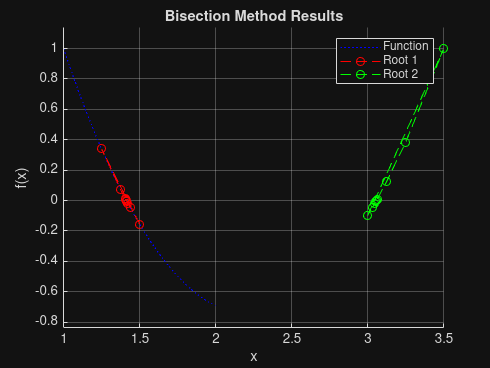

figure
hold on
fplot(func, [1, 2], 'b:')
plot(tab1.p, tab1.f_p, 'r--o')
plot(tab2.p, tab2.f_p, 'g--o')
grid on
xlabel('x');
ylabel('f(x)');
title('Bisection Method Results');
legend('Function', 'Root 1', 'Root 2');
axis equal
hold off

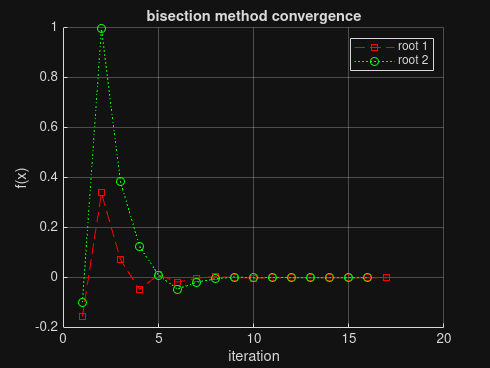

figure
hold on
plot(tab1.iter, tab1.f_p, 'r--s')
plot(tab2.iter, tab2.f_p, 'g:o')
grid on
xlabel("iteration")
ylabel("f(x)")
title("bisection method convergence")
legend("root 1", "root 2")
% ylim([-0.01, 0.01])
hold off

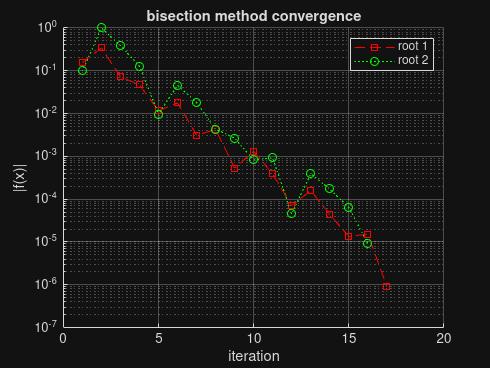

figure
hold on
plot(tab1.iter, abs(tab1.f_p), 'r--s')
plot(tab2.iter, abs(tab2.f_p), 'g:o')
grid on
xlabel("iteration")
ylabel("|f(x)|")
title("bisection method convergence")
legend("root 1", "root 2")
set(gca, "YScale", "log")
hold off